# Display_branchMVAs.mlx

## This script will display precalculated analyses of grid parameters.

#### This script changes all interpretation parameters to LaTeX.

list_factory = fieldnames(get(groot,'factory'));
index_interpreter = find(contains(list_factory,'Interpreter'));
for i = 1:length(index_interpreter)
    default_name = strrep(list_factory{index_interpreter(i)},'factory','default');
    set(groot, default_name,'latex');
end

tic
folder_name = 'saved_outputs/'; %subfolder where data will be stored

system_name = 'ieee9'

system_name = 'ieee9'


tableName = strcat(folder_name, 'nominalValuesTable_',...
    system_name, '.csv');

nominalValuesTable = readtable(tableName);

% branchesToPlot = 3;
% branchesToPlot = [1 2 3 4 5 6 7 8 9];
branchesToPlot = [1 2 3 5 8 9];

sampling_rate = nominalValuesTable.sampling_rate

sampling_rate = 0.0100

T = nominalValuesTable.T

T = 3

W = nominalValuesTable.W

W = 300


mvaflowsArrName = strcat(folder_name,'mvaflows_', ...
    system_name, '.mat');
mvaflowsArr = load(mvaflowsArrName);
mvaflowsArr = mvaflowsArr.mvaflowsArr;

bifurcationIdx = size(mvaflowsArr,1)

bifurcationIdx = 10724

indicesToPlotTruncated = 1:bifurcationIdx;
xaxisTruncated = (bifurcationIdx - indicesToPlotTruncated)...
    *sampling_rate/(60);

#### Subplot 1: MVA flows obtained from the original run.

figure('Name', 'Complete Analysis of Branch mvaflows.');
subplot(2,3,1);
plot(xaxisTruncated, mvaflowsArr(:, branchesToPlot));
set(gca,'xdir','reverse')
title('Branch MVA flows');
xlabel('Time to Bifucation (min)');
ylabel('MVA Flow Magnitude (A)');

name_labelMVAflows = strcat(folder_name, 'labelMVAflows_'...
    , system_name, '.mat');
labelMVAflows = load(name_labelMVAflows, "labelMVAflows");
labelMVAflows = labelMVAflows.labelMVAflows;
legend(labelMVAflows(branchesToPlot))

#### Subplot 2: Sp1 (Subplot 1) MVA flows passed thru GKS filter.

subplot(2,3,2);

gks_mvaflowsArr = load(strcat(folder_name, 'gks_mvaflows_', ...
    system_name, '.mat'), 'gks_mvaflowsArr');
gks_mvaflowsArr = gks_mvaflowsArr.gks_mvaflowsArr;

convolutionMargin = floor(bifurcationIdx*0.005)

convolutionMargin = 53

indicesToPlotPostConvolution = 1+convolutionMargin:bifurcationIdx-W+1;
xaxisPostConvolution = (bifurcationIdx - indicesToPlotPostConvolution)...
    *sampling_rate/(60);
plot(xaxisPostConvolution, ...
    gks_mvaflowsArr(indicesToPlotPostConvolution,branchesToPlot));
set(gca,'xdir','reverse')

title(' branch MVA flows after being passed thru GKS filter (A)');
xlabel('Time to Bifucation (min)');
ylabel('MVA Flow Magnitude (A)');

name_labelGKSMVAflows = strcat(folder_name, 'labelGKSMVAflows_'...
    , system_name, '.mat');
labelGKSMVAflows = load(name_labelGKSMVAflows, "labelGKSMVAflows");
labelGKSMVAflows = labelGKSMVAflows.labelGKSMVAflows;
legend(labelGKSMVAflows(branchesToPlot))

#### Subplot 3: Sp1 MVA flows - Sp2 MVA flows are displayed.

subplot(2,3,3);

mvaflowsDetrendedArrName = ...
    strcat(folder_name,'mvaflowsDetrended_', ...
    system_name, '.mat');
mvaflowsDetrendedArr = ...
    load(mvaflowsDetrendedArrName,'mvaflowsDetrendedArr');
mvaflowsDetrendedArr = ...
    mvaflowsDetrendedArr.mvaflowsDetrendedArr;

plot(xaxisPostConvolution, ...
    mvaflowsDetrendedArr(:, branchesToPlot));

set(gca,'xdir','reverse')
title({['Detrended MVA flows after subtracting '] ...
    ['the GKS signal from the original (A)']});
xlabel('Time to Bifucation (min)');
ylabel('Detrended mvaflows (A)');

name_labelDeltaMVAflows = strcat(folder_name, 'labelDeltaMVAflows_'...
    , system_name, '.mat');
labelDeltaMVAflows = load(name_labelDeltaMVAflows, "labelDeltaMVAflows");
labelDeltaMVAflows = labelDeltaMVAflows.labelDeltaMVAflows;

#### Subplot 4: AR1(Sp3 MVA flows)

ar1_vector = ...
    load(strcat(folder_name,'ar1_vector_mvaflows_', ...
    system_name, '_', num2str(T), '_sec.mat'),'ar1_vector');

ar1_vector = ar1_vector.ar1_vector;

indicesToPlotPostParametrization = 1+convolutionMargin:bifurcationIdx-2*W+1;
xaxisPostParametrization = (bifurcationIdx - indicesToPlotPostParametrization)...
    *sampling_rate/(60);

subplot(2,3,4)
plot(xaxisPostParametrization, ar1_vector(:, branchesToPlot));
% yyaxis left
set(gca,'xdir','reverse')
xlabel3 = xlabel('Time to bifurcation (minutes)');
% yticks3 = yticks;
ylabel3 = ylabel('$a_1$');
% ylabel3.Color = colors(1,:);
title('Autocorrelation values');

name_labelARDeltaMVAflows = strcat(folder_name, 'labelARDeltaMVAflows_'...
    , system_name, '.mat');
labelARDeltaMVAflows = ...
    load(name_labelARDeltaMVAflows, "labelARDeltaMVAflows");
labelARDeltaMVAflows = labelARDeltaMVAflows.labelARDeltaMVAflows;
legend(labelARDeltaMVAflows(branchesToPlot))

#### Subplot 5: Var(Sp3 MVA flows)

var_vector = ...
    load(strcat(folder_name,'var_vector_mvaflows_', ...
    system_name, '_', num2str(T), '_sec.mat'), 'var_vector');

var_vector = var_vector.var_vector;

subplot(2,3,5)
plot(xaxisPostParametrization, var_vector(:, branchesToPlot));
% yyaxis left
set(gca,'xdir','reverse')
% yyaxis right
ylabel4 = ylabel('$\sigma^2$');
% ylabel4.Color = colors(2,:);
% yticks4 = yticks;
% set(gca,'ycolor',colors(2,:))
% set(gca,'xdir','reverse')
xlabel4 = xlabel('Time to bifurcation (minutes)');
title('Variance values');

name_labelVarDeltaMVAflows = strcat(folder_name, 'labelVarDeltaMVAflows_'...
    , system_name, '.mat');
labelVarDeltaMVAflows =...
    load(name_labelVarDeltaMVAflows, "labelVarDeltaMVAflows");
labelVarDeltaMVAflows = labelVarDeltaMVAflows.labelVarDeltaMVAflows;
legend(labelVarDeltaMVAflows(branchesToPlot))

#### Print the figure.

pdf_location_name = 'pdf/'

pdf_location_name = 'pdf/'

if T < 1
    windowInSec = strcat('point',string(10*T),'_sec');
else
    windowInSec = strcat(string(T),'_sec');
end
imagePdfName = strcat(pdf_location_name, '_', system_name,...
    'branchMVAflows_',num2str(branchesToPlot),'_T_',windowInSec)

imagePdfName = "pdf/_ieee9branchMVAflows_1  2  3  5  8  9_T_3_sec"

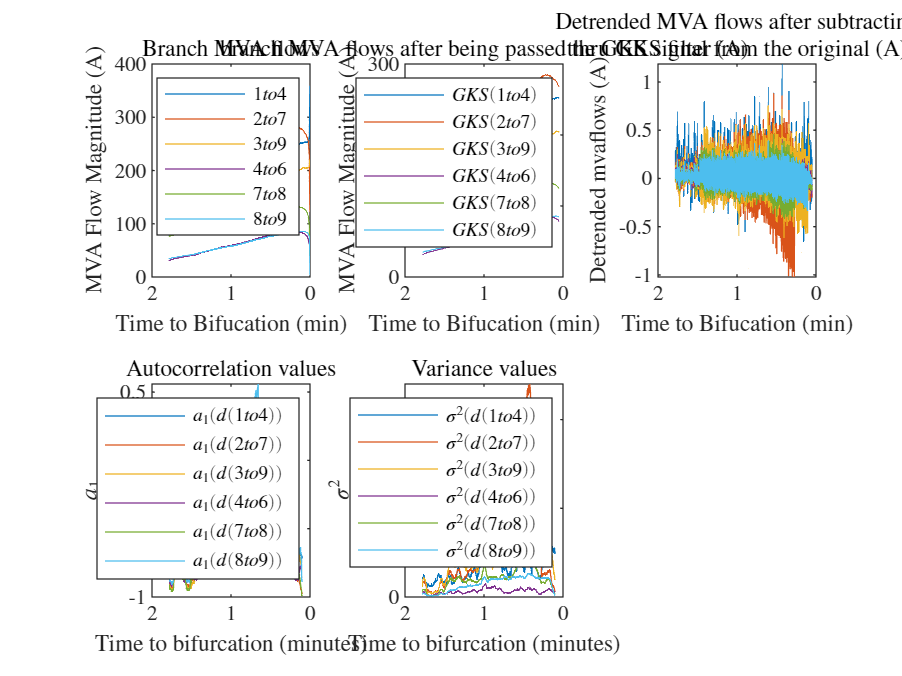


set(gcf, 'PaperSize', [24 12]); %set the paper size to what you want  
print(imagePdfName,'-dpdf', '-fillpage') % then print it